
% MATLAB Code to Compare Two Data Sets from LT-Spice with Enhanced Line Width and Legends
% Load the Randle circuit data
filename_randle = 'Randle circuit 1 alt[2].csv';
data_randle = readtable(filename_randle, 'Delimiter', '\t');


% Load the Warburg element data
filename_warburg = 'Warbrug element 5 stage.csv';
data_warburg = readtable(filename_warburg, 'Delimiter', '\t');

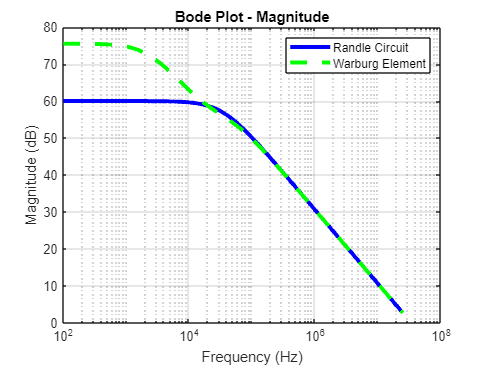


% Extract frequency and combined magnitude-phase data for Randle circuit
frequency_randle = data_randle{:, 'Freq_'};
combined_randle = data_randle{:, 'V_input__I_V1_'};

% Extract frequency and combined magnitude-phase data for Warburg element
frequency_warburg = data_warburg{:, 'Freq_'};
combined_warburg = data_warburg{:, 'V_input__I_V1_'};

% Parse magnitude (in dB) and phase (in degrees) for Randle circuit
num_entries_randle = length(combined_randle);
magnitude_randle_db = zeros(num_entries_randle, 1);
phase_randle_deg = zeros(num_entries_randle, 1);

for i = 1:num_entries_randle
    match = regexp(combined_randle{i}, '\(([^dB]+)dB,([^°]+)°\)', 'tokens');
    magnitude_randle_db(i) = str2double(match{1}{1});
    phase_randle_deg(i) = str2double(match{1}{2});
end

% Parse magnitude (in dB) and phase (in degrees) for Warburg element
num_entries_warburg = length(combined_warburg);
magnitude_warburg_db = zeros(num_entries_warburg, 1);
phase_warburg_deg = zeros(num_entries_warburg, 1);

for i = 1:num_entries_warburg
    match = regexp(combined_warburg{i}, '\(([^dB]+)dB,([^°]+)°\)', 'tokens');
    magnitude_warburg_db(i) = str2double(match{1}{1});
    phase_warburg_deg(i) = str2double(match{1}{2});
end

% Plot Bode Magnitude
figure;
semilogx(frequency_randle, magnitude_randle_db, 'b', 'LineWidth', 3, 'DisplayName', 'Randle Circuit');
hold on;
semilogx(frequency_warburg, magnitude_warburg_db, 'g--', 'LineWidth', 3, 'DisplayName', 'Warburg Element');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Bode Plot - Magnitude');
legend('Randle Circuit', 'Warburg Element'); % Adding legend
grid on;


% Plot Bode Phase
figure;
semilogx(frequency_randle, phase_randle_deg, 'b', 'LineWidth', 3, 'DisplayName', 'Randle Circuit');
hold on;
semilogx(frequency_warburg, phase_warburg_deg, 'g--', 'LineWidth', 3, 'DisplayName', 'Warburg Element');
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
title('Bode Plot - Phase');
legend('Randle Circuit', 'Warburg Element'); % Adding legend
grid on;

% Plot Nyquist
figure;
real_randle = 10.^(magnitude_randle_db / 20) .* cosd(phase_randle_deg);
imag_randle = 10.^(magnitude_randle_db / 20) .* sind(phase_randle_deg);

real_warburg = 10.^(magnitude_warburg_db / 20) .* cosd(phase_warburg_deg);
imag_warburg = 10.^(magnitude_warburg_db / 20) .* sind(phase_warburg_deg);

plot(real_randle, imag_randle, 'b', 'LineWidth', 3, 'DisplayName', 'Randle Circuit');
hold on;
plot(real_warburg, imag_warburg, 'g--', 'LineWidth', 3, 'DisplayName', 'Warburg Element');
xlabel('Real Part');
ylabel('Imaginary Part');
title('Nyquist Plot');
legend('Randle Circuit', 'Warburg Element'); % Adding legend
grid on;